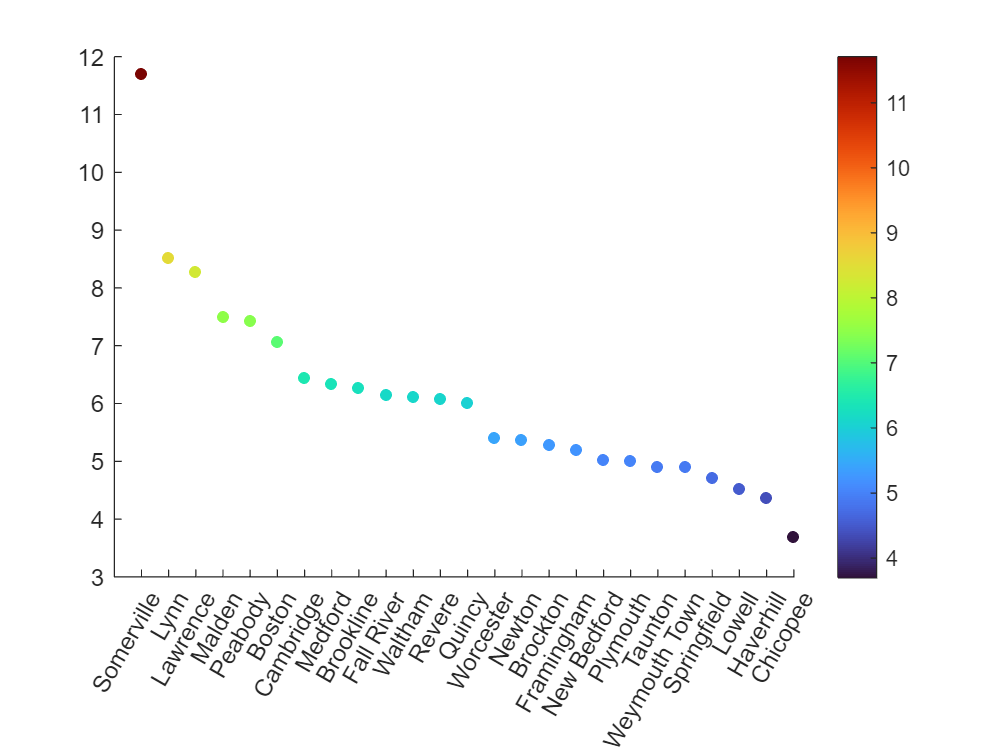

affordability = homeprices ./ incomes;
municipalities = table2array(Data(2:end, "municipality"));

n = length(affordability);

% sort affordability, keep order index, replace affordability with sorted vector
[affordability, ix] = sort(affordability, "descend");

% reorder municipalities to match
municipalities = municipalities(ix);  

color = affordability;
scatter(1:n, affordability, 25, color, "filled")
colormap("turbo");
xticks([1:25]);
xticklabels(municipalities);
xtickangle(60);
colorbar